# Laborator 2

## Problema 1

Se dă problema Cauchy

$\Bigg\{$$\begin{array}{l}
y^{\prime } \left(t\right)=y\left(t\right)-t^2 +1,\\
y\left(0\right)=0\ldotp 5,t\in \left\lbrack 0,2\right\rbrack 
\end{array}$.  

Rezolvați folosind

a) Metoda dezvoltării în serie Taylor pentru $n=2,3,4$;

b) Metoda lui Euler modificată;

c) Metoda lui Heun.

Comparați soluțiile obținute între ele și cu soluția analitică $y\left(t\right)={\left(t+1\right)}^2 -\frac{1}{2}e^t$.

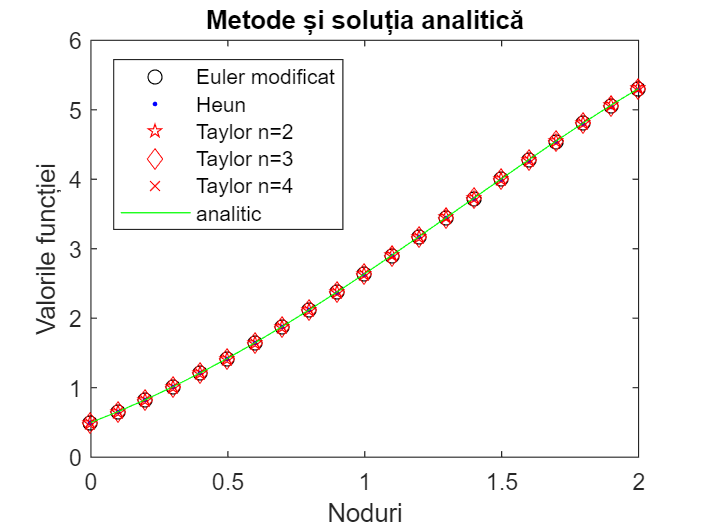

a=0; 
b=2;
N=21;
y0=0.5;
[t_EM,y_EM]=eulerM('func',a,b,N,y0);
[t_H,y_H]=heun('func',a,b,N,y0);
[t_T2,y_T2]=taylor2(a,b,N,y0);
[t_T3,y_T3]=taylor3(a,b,N,y0);
[t_T4,y_T4]=taylor4(a,b,N,y0);
 
t_ex=a:0.1:b;
y_ex=(t_ex+1).^2-0.5*exp(t_ex);	
plot(t_EM,y_EM,'ok', t_H,y_H, '.b',t_T2,y_T2, 'rp', t_T3,y_T3,'rd', ...
    t_T4,y_T4,'rx',t_ex, y_ex, 'g' )
title('Metode și soluția analitică')
xlabel('Noduri')
ylabel('Valorile funcției')
legend('Euler modificat', 'Heun','Taylor n=2', 'Taylor n=3','Taylor n=4', 'analitic', ...
    Location ='best')

## Funcții utilizate

### heun

function [x,y]=heun(f,a,b,N,y0)
    h=(b-a)/(N-1);
    y=zeros(N,length(y0));
    y(1,:)=y0;
    t=a:h:b;
    x=t;
    for i=2:N
        K1=feval(f,t(i-1),y(i-1,:));
        K2=feval(f,t(i-1)+h,y(i-1,:)+h*K1);
        y(i,:)=y(i-1,:)+0.5*h*(K1+K2);
    end
end

### func

function dy=func(t,y)
    dy=y-t^2+1;
end

### eulerM

function [x,y]=eulerM(f,a,b,N,y0)
    h=(b-a)/(N-1);
    y=zeros(N,length(y0));
    y(1,:)=y0;
    t=a:h:b;
    x=t;
    for i=2:N
        K1=feval(f,t(i-1),y(i-1,:));
        K2=feval(f,t(i-1)+0.5*h,y(i-1,:)+0.5*h*K1);
        y(i,:)=y(i-1,:)+h*K2;
    end
end

### taylor2

function [x,y]=taylor2(a,b,N,y0)
    h=(b-a)/(N-1);
    y=zeros(N,1);
    y(1)=y0;
    t=a:h:b;
    x=t;
    for i=2:N
        y(i)=y(i-1)+h*(y(i-1)-t(i-1)^2+1+0.5*h*(y(i-1)-t(i-1)^2-2*t(i-1)+1));
    end
end

### taylor3

function [x,y]=taylor3(a,b,N,y0)
    h=(b-a)/(N-1);
    y=zeros(N,1);
    y(1)=y0;
    t=a:h:b;
    x=t;
    for i=2:N
        y(i)=y(i-1)+h*(y(i-1)-t(i-1)^2+1+0.5*h*(y(i-1)-t(i-1)^2-2*t(i-1)+1)+1/6*h^2* ...
            (y(i-1)-t(i-1)^2-2*t(i-1)-1));
    end
end

### taylor4

function [x,y]=taylor4(a,b,N,y0)
    h=(b-a)/(N-1);
    y=zeros(N,1);
    y(1)=y0;
    t=a:h:b;
    x=t;
    for i=2:N
        y(i)=y(i-1)+h*(y(i-1)-t(i-1)^2+1+0.5*h*(y(i-1)-t(i-1)^2-2*t(i-1)+1)+1/6*h^2* ...
            (y(i-1)-t(i-1)^2+1-2*t(i-1)-2)+1/24*h^3*(y(i-1)-t(i-1)^2+1-2*t(i-1)-2));
    end
end